## Example 3-42 [2]

For the space truss subjected to a 10 kN load in the *x* direction, as shown in Figure **P3–42**, determine the displacement of node 5. Also determine the stresses in each element. Let *A = 25 × 10⁻⁴ m²* and *E = 2 × 10¹¹ N/m² *for all elements. The coordinates of each node, in millimeters, are shown in the figure. Nodes 1–4 are supported by ball-and-socket joints (fixed supports).

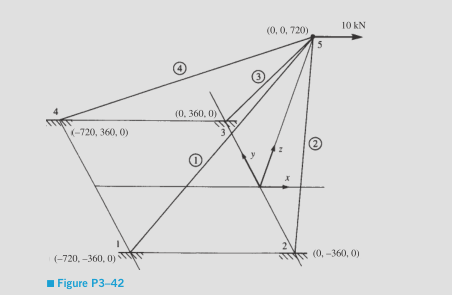

% Geometry


connect_vec = [1 5; 2 5; 3 5; 4 5];

crd = [ -720, -360,   0;
           0, -360,   0;
           0,  360,   0;
        -720,  360,   0;
           0,    0, 720 ];


len = zeros(1,4);
len([2,3]) = norm(crd(5,:) - crd(2,:));
len([1,4]) = norm(crd(5,:) - crd(1,:))

len = 1.0e+03 *

    1.0800    0.8050    0.8050    1.0800



% Mechanical data

E = 2e11*ones(1,4); 
A = 25e-4*ones(1,4);
stf = BarElStiffness(E,A,len);

% Defining BCs
a_vec = [0 0 0 0 0 0 0 0 0 0 0 0 1 1 1]

a_vec =      0     0     0     0     0     0     0     0     0     0     0     0     1     1     1



F = zeros(15,1); 
F(13) = 10e3;  %Fa
U = zeros(15,1); 

Fa = F(a_vec ~= 0);
Uc = U(a_vec == 0); 

KG = KAssembly(connect_vec,stf,crd,"3d");      
M = partitionMatrix(KG,a_vec);

[Ua, Fc] = UFSolver(M,Uc,Fa);
U(a_vec == 1) = Ua

U =          0
         0
         0
         0
         0
         0
         0
         0
         0
         0
         0
         0
    0.0344
   -0.0000
   -0.0101


F(a_vec == 0) = Fc

F =        -5000
       -2500
       -5000
           0
        2500
        5000
           0
       -2500
        5000
       -5000
        2500
       -5000
       10000
           0
           0



[STRAIN, STRESS] = postProcess(connect_vec,crd,U,E,"3d")

STRAIN = 1.0e-04 *

    0.1500
   -0.1118
   -0.1118
    0.1500


STRESS = 1.0e+06 *

    3.0000
   -2.2361
   -2.2361
    3.0000



% Changing coordinates for a better visualization (optional) 
%crd = [-crd(:,2), crd(:,3), crd(:,1)]

crd =    360     0  -720
   360     0     0
  -360     0     0
  -360     0  -720
     0   720     0


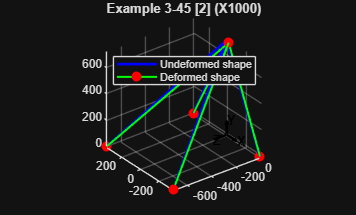

plotTruss(connect_vec,crd,U,1000, "Example 3-45 [2]",100)  


% Check for equilibrium
assert(sum(F) < 1e-6)